# Maze Problem

## BFS and DFS

Breadth-first search (BFS) is a simple strategy in which the root node is expanded first, then all the successors of the root node are expanded next, then their successors, and so on. In general, all the nodes are expanded at a given depth in the search tree before any nodes at the next level are expanded.

Breadth-first search is an instance of the general graph-search algorithm in which the shallowest unexpanded node is chosen for expansion. This is achieved very simply by using a FIFO queue for the frontier.

Depth-first search (DFS) always expands  the deepest node in the current frontier of the search tree. The search proceeds immediately to the deepest level of the search tree, where the nodes have no successors. As those nodes are expanded, they are dropped from the frontier, so then the search “backs up” to the next

deepest node that still has unexplored successors.

The depth-first search algorithm is an instance of the graph-search algorithm by using a LIFO queue.

A LIFO queue means that the most recently generated node is chosen for expansion. This must be the deepest unexpanded node because it is one deeper than its parent—which, in turn, was the deepest unexpanded node when it was selected.

## Problem

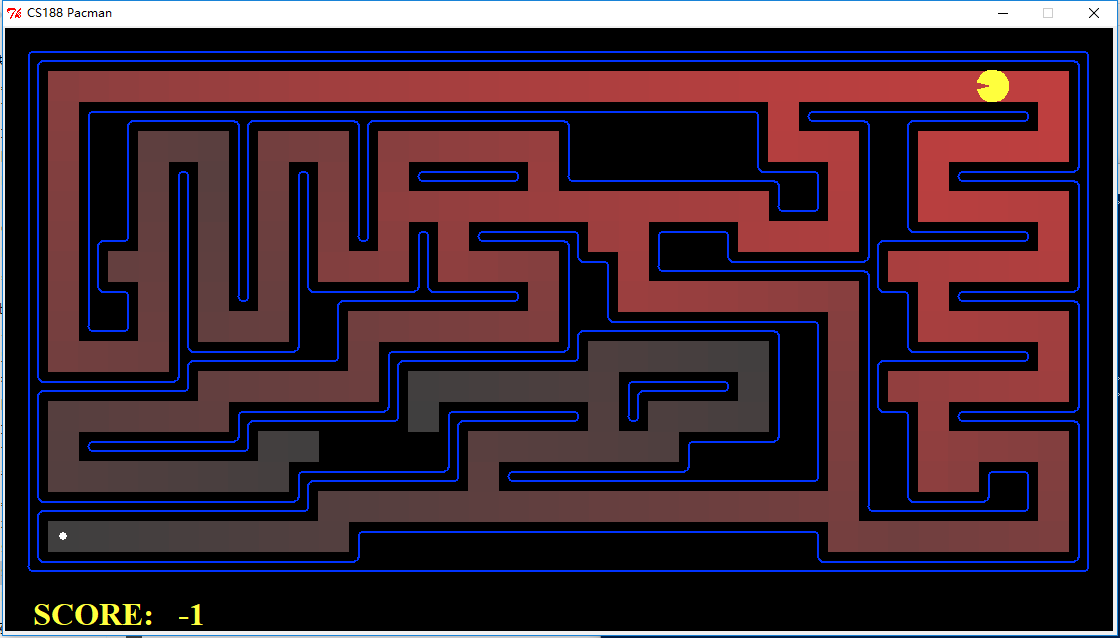

Task:

Please solve the maze problem (i.e., find the shortest path from the start point to the finish point) by using BFS or DFS (MATLAB).

## Analysis

The picture can be modelled as a 0-1 matrix as following:

111111111111111111111111111111111111
100000000000000000000000000000000021
101111111111111111111111101111111101
101100010001000000111111100011000001
101101010101011110111111111011011111
101101010101000000000000011011000001
101101010101010111100111000011111101
101001010100010000110111111110000001
101101010111111110110000000011011111
101101000110000000111111111011000001
100001111110111111100000011011111101
111111000000100000001111011010000001
100000011111101111101000011011011111
101111110000001000000011111011000001
100000000111111011111111111011001101
111111111100000000000000000011111101
130000000001111111111111111000000001
111111111111111111111111111111111111

Note that "2" is the start point, "3" the finish point. The wall is made of "0"s and the path can be found by "1"s.

BFS cound find the shortest path, while DFS could not. Instead, we can find the shortest path by calling DFS many times.

## Code

function BFS_MAZE(maze)
clear;
% start point is labeled as "2"
% end point is labeled as "3"
maze=[1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 
1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 2 1 
1 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 0 1 1 1 1 1 1 1 1 0 1 
1 0 1 1 0 0 0 1 0 0 0 1 0 0 0 0 0 0 1 1 1 1 1 1 1 0 0 0 1 1 0 0 0 0 0 1 
1 0 1 1 0 1 0 1 0 1 0 1 0 1 1 1 1 0 1 1 1 1 1 1 1 1 1 0 1 1 0 1 1 1 1 1 
1 0 1 1 0 1 0 1 0 1 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 1 1 0 1 1 0 0 0 0 0 1 
1 0 1 1 0 1 0 1 0 1 0 1 0 1 0 1 1 1 1 0 0 1 1 1 0 0 0 0 1 1 1 1 1 1 0 1 
1 0 1 0 0 1 0 1 0 1 0 0 0 1 0 0 0 0 1 1 0 1 1 1 1 1 1 1 1 0 0 0 0 0 0 1 
1 0 1 1 0 1 0 1 0 1 1 1 1 1 1 1 1 0 1 1 0 0 0 0 0 0 0 0 1 1 0 1 1 1 1 1 
1 0 1 1 0 1 0 0 0 1 1 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 1 0 1 1 0 0 0 0 0 1 
1 0 0 0 0 1 1 1 1 1 1 0 1 1 1 1 1 1 1 0 0 0 0 0 0 1 1 0 1 1 1 1 1 1 0 1 
1 1 1 1 1 1 0 0 0 0 0 0 1 0 0 0 0 0 0 0 1 1 1 1 0 1 1 0 1 0 0 0 0 0 0 1 
1 0 0 0 0 0 0 1 1 1 1 1 1 0 1 1 1 1 1 0 1 0 0 0 0 1 1 0 1 1 0 1 1 1 1 1 
1 0 1 1 1 1 1 1 0 0 0 0 0 0 1 0 0 0 0 0 0 0 1 1 1 1 1 0 1 1 0 0 0 0 0 1 
1 0 0 0 0 0 0 0 0 1 1 1 1 1 1 0 1 1 1 1 1 1 1 1 1 1 1 0 1 1 0 0 1 1 0 1 
1 1 1 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 1 1 1 1 1 0 1 
1 3 0 0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 1 
1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1];
% a copy of maze
maze2 = maze;
% define 4 search directions
directions = [-1,1,0,0;0,0,-1,1];
% store the solutionution
remark = zeros(100,3);
% find the start point
[I,J] = find(maze == 2);
remark(1,:) = [I,J,-1];
count = 2;
search(1);
solution = remark(count-1,:);

while(solution(end,3) > 0)
    solution = [solution;remark(solution(end,3),:)];
end
maze2(sub2ind(size(maze), solution(2:end-1,1), solution(2:end-1,2))) = 5;
%disp(maze2);
disp(solution(:,1:2)'); % print the route

    function search(front)
        x = remark(front,1);
        y = remark(front,2);        
        for i = 1 : 4
            if cango(x + directions(1,i),y + directions(2,i))
                remark(count,1) = x + directions(1,i);
                remark(count,2) = y + directions(2,i);
                remark(count,3) = front;
                count = count + 1;
                if maze(x + directions(1,i),y + directions(2,i)) ~= 3
                    maze(x + directions(1,i),y + directions(2,i)) = 5;
                else
                    return;
                end
                
            end
        end
        search(front + 1);
    end
% decide whether the point can be passed by
    function z = cango(x,y)
        % decide the border
        z = true;
        try
            if ismember(maze(x,y),[1,2,5])
                z = false;
            end
        catch
            z = false;
        end
    end
end

## Results

The route is as following (like (17,2) (17,3) ...): 

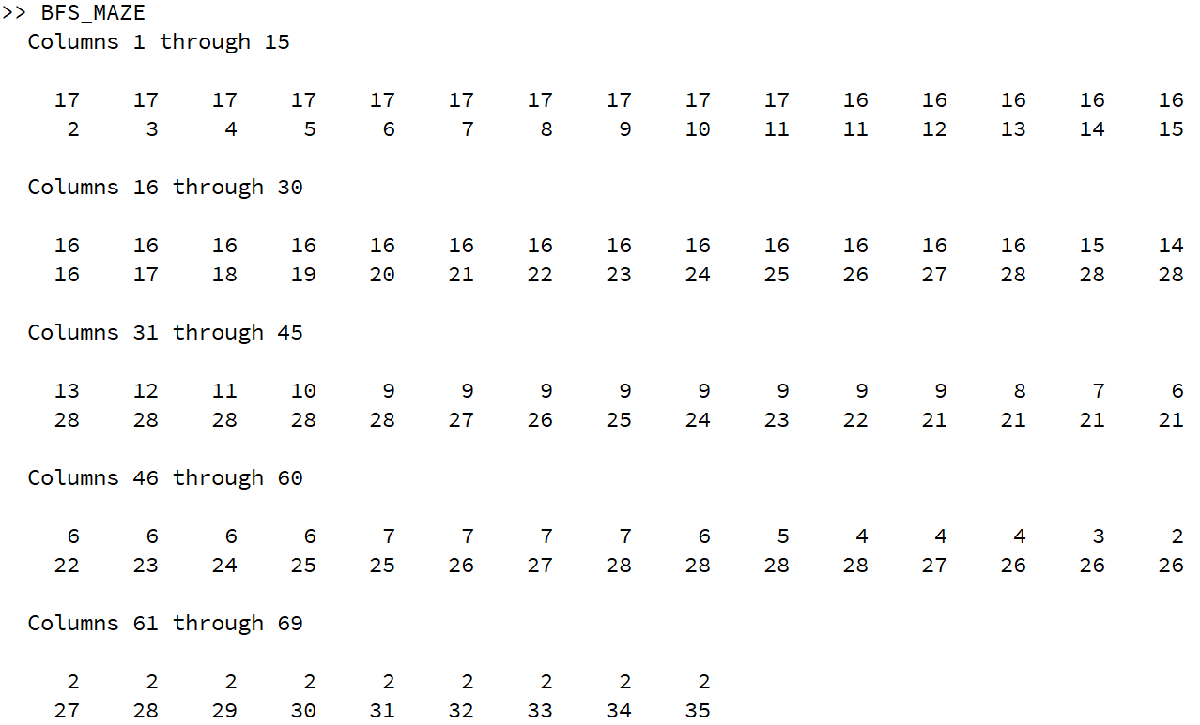

## More

In MATLAB, there is a function \texttt{shortest} which can Solve shortest path problem in biograph object.

**Syntax:**

[dist, path, pred] = shortestpath(BGObj, S)

[dist, path, pred] = shortestpath(BGObj, S, T)

[...] = shortestpath(..., 'Directed', DirectedValue, ...)

[...] = shortestpath(..., 'Method', MethodValue, ...)

[...] = shortestpath(..., 'Weights', WeightsValue, ...)

## Reference 

Russell, Stuart J., and Peter Norvig. *Artificial Intelligence - A Modern Approach, Third International Edition*. Pearson Education, 2010. 

[UC Berkeley CS188 Intro to AI -- Course Materials](http://ai.berkeley.edu/project_overview.html)

[Solve shortest path problem in biograph object](https://ww2.mathworks.cn/help/bioinfo/ref/shortestpathbiograph.html?searchHighlight=bfs&s_tid=srchtitle)